**TALLER 11 MODELO EPIDEMIOLÓGICO SIRV**

**INVASIÓN ZOMBIE**

**POR VALENTINA RAMIREZ RIOS**

**OBJETIVO**

El objetivo de este taller es resolver numéricamente, por el método numérico de Runge-Kutta implementado en la función [ode45](https://www.mathworks.com/help/matlab/ref/ode45.html) de MATLAB, la ecuación de estado de un modelo epidemiológico [SIRV](https://en.wikipedia.org/wiki/Compartmental_models_in_epidemiology#The_SIRV_model) (SIR con vacunados) no lineal en un archivo Live Script de MATLAB y analizar el resultado.

**DESARROLLO**

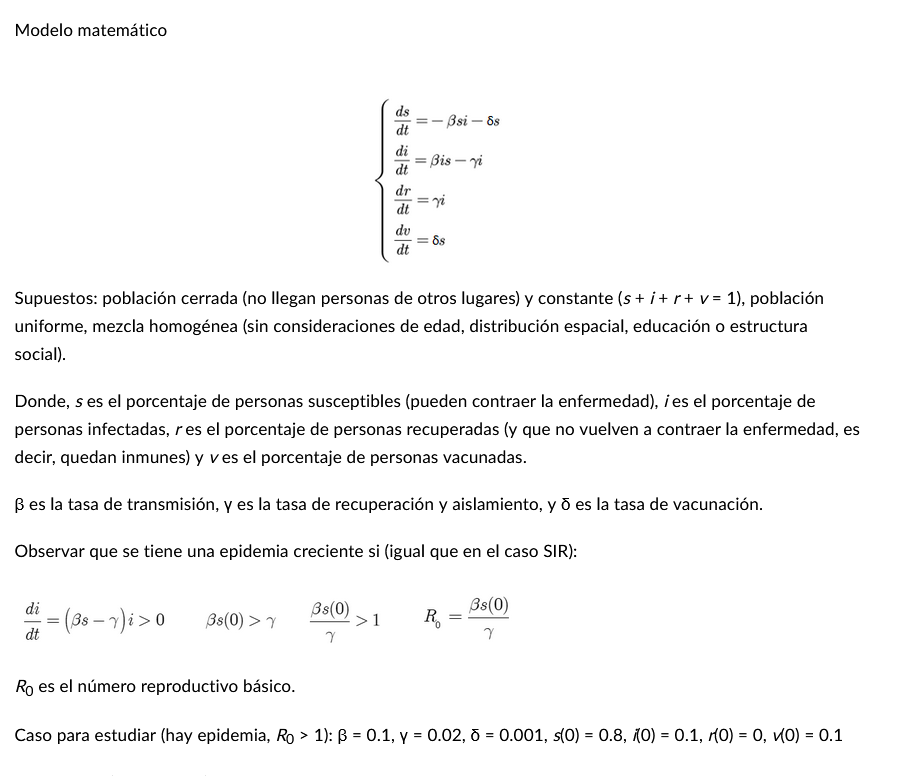

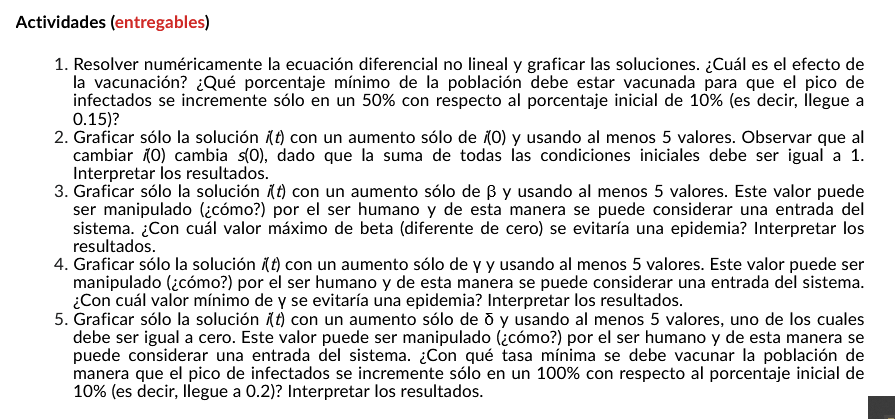

% Defino las variables de estado
syms S(t) I(t) R(t) V(t)

% Defino las derivadas

% susceptibles zombies
dszombies = diff(S(t),t,1); 

% infectados zombies
dizombies = diff(I(t),t,1);

% recuperados zombies
drzombies = diff(R(t),t,1);

% vacunados zombies
dvzombies = diff(V(t),t,1);

% Espacio de solucion temporal
% Tiempo de muestreo para la invasion zombie
% Tiempo de muestreo 1 dia
ts = 1;

% Muestreo de 1 año
tmin = 0;
tmax = 365;

% Construir el vector de tiempo para la solucion
tspan = tmin:ts:tmax;

% Definir las constantes
% Tasa de transmision
beta = 0.1;

% Tasa de vacunacion
gamma = 0.01;

% Tasa de recuperacion
delta = 0.02;

% Definir las condiciones iniciales que deben sumar 1
Ci_sz = 0.8;
Ci_iz = 0.1;
Ci_rz = 0;
Ci_vz = 0.1;

% Como se va a resolver numericamente, se arma el vector de condiciones iniciales
Ci_zombies = [Ci_sz Ci_iz Ci_rz Ci_vz];

% Definir las ecuaciones de estado para la invasion zombie

Tasa_szombies = -beta*S*I-delta*S;
Tasa_izombies = beta*I*S-gamma*I;
Tasa_rzombies = gamma*I;
Tasa_vzombies = delta*S;

% Usar el comando ODE45 para resolver

Funciones_estado = odeFunction([Tasa_szombies Tasa_izombies Tasa_rzombies Tasa_vzombies],[S I R V]);

% Resolver usando el comando ODE45
[tiempo,Salida] = ode45(Funciones_estado,tspan,Ci_zombies);



**PUNTO 1: **

Resolver numéricamente la ecuación diferencial no lineal y graficar las soluciones. ¿Cuál es el efecto de la vacunación? ¿Qué porcentaje mínimo de la población debe estar vacunada para que el pico de infectados se incremente sólo en un 50% con respecto al porcentaje inicial de 10% (es decir, llegue a 0.15)?

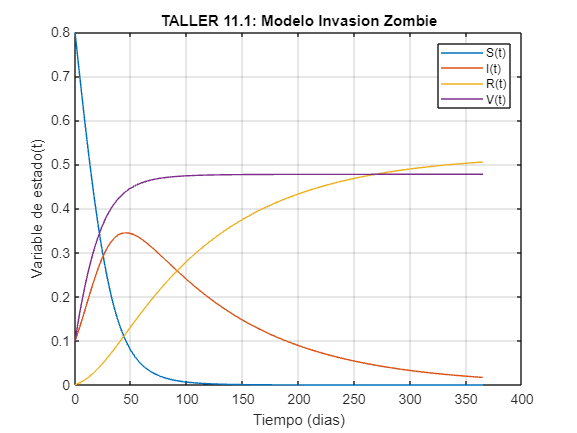

% Punto 1: Simulacion
% Graficar la solucion
figure
plot(tiempo,Salida)
grid on
hold on
xlabel('Tiempo (dias)')
ylabel ('Variable de estado(t)')
title('TALLER 11.1: Modelo Invasion Zombie')
legend('S(t)','I(t)','R(t)','V(t)')

Segun la grafica, el efecto de la vacunación a medida que la tasa crece y se vuelve constante, hace que disminuya progresivamente la tasa de los infectados a lo largo del año, volviendose a casi 0 el valor de esta tasa al finalizar el año; ademas, la tasa de los susceptibles decrece a casi 0 desde los 100 dias aproximadamente.

El porcentaje minimo de la poblacion que debe estar vacunada para que el pico de infectados se incremente solo en un 50% con respecto al 10% que es el porcentaje inicial seria aproximadamente del 100%, osea doble con respecto al porcentaje inicial de los vacunados. 

**PUNTO 2: **

Graficar sólo la solución *i*(*t*) con un aumento sólo de *i*(0) y usando al menos 5 valores. Observar que al cambiar *i*(0) cambia *s*(0), dado que la suma de todas las condiciones iniciales debe ser igual a 1. Interpretar los resultados.

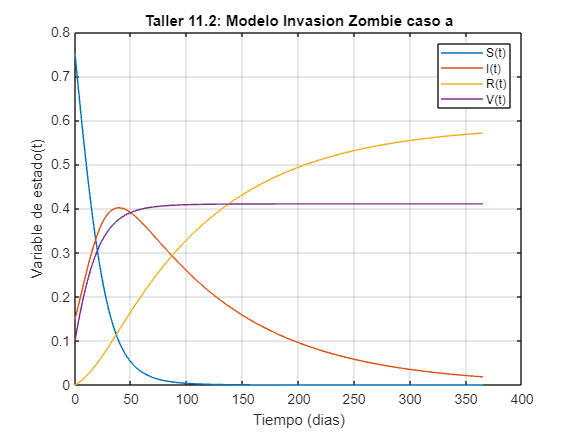

% Punto 2: Cambiar las condiciones inciales de los infectados zombies
% manteniendo en 1 el valor total de las condiciones iniciales

% Caso a
% Defino condiciones iniciales que deben sumar 1

Ci_sz = 0.75;
Ci_iz = 0.15;
Ci_rz = 0;
Ci_vz = 0.1;

% Como se resolverá numericamente, se arma el vector de condiciones iniciales

Ci_zombies = [Ci_sz Ci_iz Ci_rz Ci_vz];

% Usar el comando ODE45 para resolver
Funciones_estado = odeFunction([Tasa_szombies Tasa_izombies Tasa_rzombies Tasa_vzombies],[S I R V]);

% Resolver usando el comando ODE45
[tiempo,Salida] = ode45(Funciones_estado,tspan,Ci_zombies);

% Simular
% Graficar la solucion
figure
plot(tiempo,Salida)
grid on
hold on
xlabel('Tiempo (dias)')
ylabel ('Variable de estado(t)')
title('Taller 11.2: Modelo Invasion Zombie caso a')
legend('S(t)','I(t)','R(t)','V(t)')

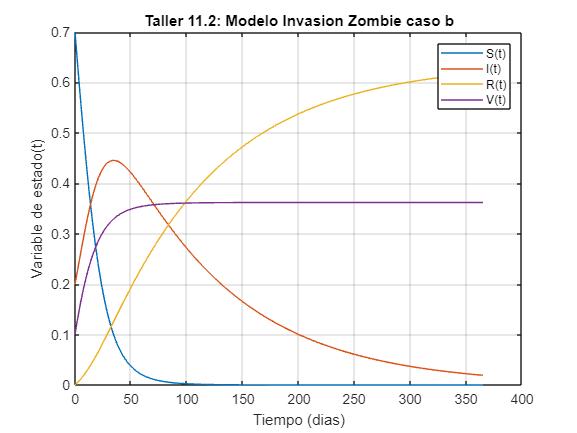

%Caso b
% Defino condiciones iniciales que deben sumar 1

Ci_sz = 0.7;
Ci_iz = 0.2;
Ci_rz = 0;
Ci_vz = 0.1;

% Como se resolverá numericamente, se arma el vector de condiciones iniciales

Ci_zombies = [Ci_sz Ci_iz Ci_rz Ci_vz];

% Usar el comando ODE45 para resolver
Funciones_estado = odeFunction([Tasa_szombies Tasa_izombies Tasa_rzombies Tasa_vzombies],[S I R V]);

% Resolver usando el comando ODE45
[tiempo,Salida] = ode45(Funciones_estado,tspan,Ci_zombies);

% Simular
% Graficar la solucion
figure
plot(tiempo,Salida)
grid on
hold on
xlabel('Tiempo (dias)')
ylabel ('Variable de estado(t)')
title('Taller 11.2: Modelo Invasion Zombie caso b')
legend('S(t)','I(t)','R(t)','V(t)')

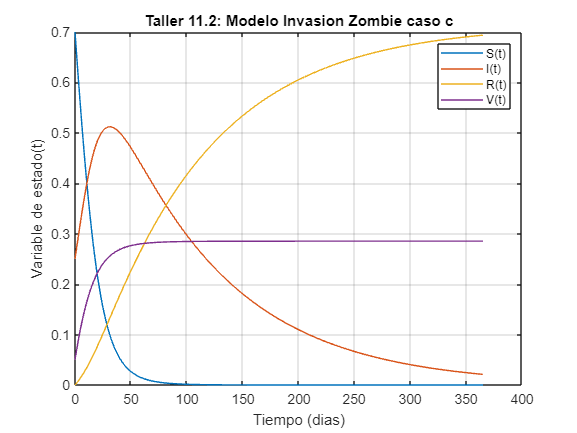


%Caso c
% Defino condiciones iniciales que deben sumar 1

Ci_sz = 0.7;
Ci_iz = 0.25;
Ci_rz = 0;
Ci_vz = 0.05;

% Como se resolverá numericamente, se arma el vector de condiciones iniciales

Ci_zombies = [Ci_sz Ci_iz Ci_rz Ci_vz];

% Usar el comando ODE45 para resolver
Funciones_estado = odeFunction([Tasa_szombies Tasa_izombies Tasa_rzombies Tasa_vzombies],[S I R V]);

% Resolver usando el comando ODE45
[tiempo,Salida] = ode45(Funciones_estado,tspan,Ci_zombies);

% Simular
% Graficar la solucion
figure
plot(tiempo,Salida)
grid on
hold on
xlabel('Tiempo (dias)')
ylabel ('Variable de estado(t)')
title('Taller 11.2: Modelo Invasion Zombie caso c')
legend('S(t)','I(t)','R(t)','V(t)')

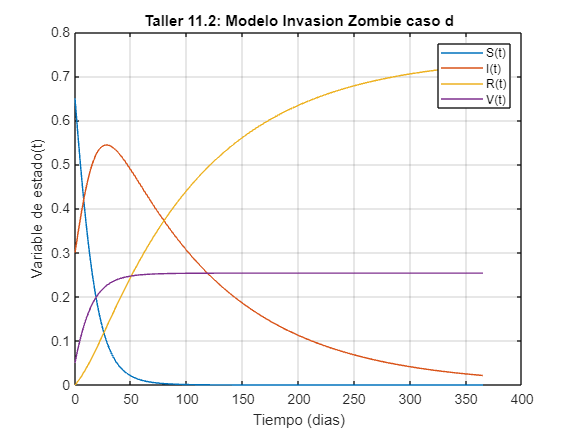

%Caso d
% Defino condiciones iniciales que deben sumar 1

Ci_sz = 0.65;
Ci_iz = 0.3;
Ci_rz = 0;
Ci_vz = 0.05;

% Como se resolverá numericamente, se arma el vector de condiciones iniciales

Ci_zombies = [Ci_sz Ci_iz Ci_rz Ci_vz];

% Usar el comando ODE45 para resolver
Funciones_estado = odeFunction([Tasa_szombies Tasa_izombies Tasa_rzombies Tasa_vzombies],[S I R V]);

% Resolver usando el comando ODE45
[tiempo,Salida] = ode45(Funciones_estado,tspan,Ci_zombies);

% Simular
% Graficar la solucion
figure
plot(tiempo,Salida)
grid on
hold on
xlabel('Tiempo (dias)')
ylabel ('Variable de estado(t)')
title('Taller 11.2: Modelo Invasion Zombie caso d')
legend('S(t)','I(t)','R(t)','V(t)')

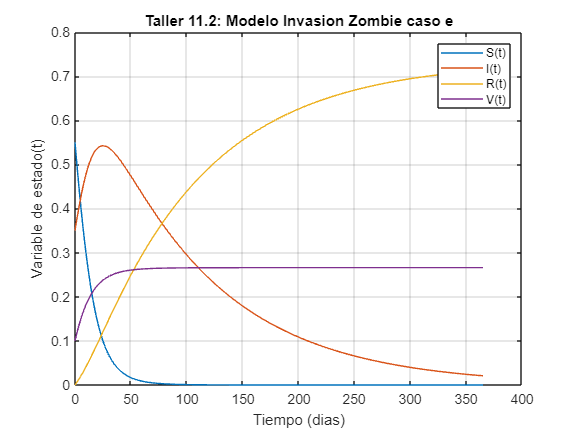

%Caso e
% Defino condiciones iniciales que deben sumar 1

Ci_sz = 0.55;
Ci_iz = 0.35;
Ci_rz = 0;
Ci_vz = 0.1;

% Como se resolverá numericamente, se arma el vector de condiciones iniciales

Ci_zombies = [Ci_sz Ci_iz Ci_rz Ci_vz];

% Usar el comando ODE45 para resolver
Funciones_estado = odeFunction([Tasa_szombies Tasa_izombies Tasa_rzombies Tasa_vzombies],[S I R V]);

% Resolver usando el comando ODE45
[tiempo,Salida] = ode45(Funciones_estado,tspan,Ci_zombies);

% Simular
% Graficar la solucion
figure
plot(tiempo,Salida)
grid on
hold on
xlabel('Tiempo (dias)')
ylabel ('Variable de estado(t)')
title('Taller 11.2: Modelo Invasion Zombie caso e')
legend('S(t)','I(t)','R(t)','V(t)')

Segun los 5 casos presentados, que tuvieron como variación incrementar el valor de la tasa de los infectados, manteniendo las condiciones iniciales en que sumen 1, se puede afirmar que a medida que se incrementa el valor de la tasa de los infectados, disminuye la tasa de los susceptibles ya que siempre se trabaja con la misma poblacion, donde las condiciones iniciales se mantienen en una suma de 1 por lo que los valores mantienen una misma condicion inicial.

**PUNTO 3:**

Graficar sólo la solución *i*(*t*) con un aumento sólo de β y usando al menos 5 valores. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema. ¿Con cuál valor máximo de beta (diferente de cero) se evitaría una epidemia? Interpretar los resultados.

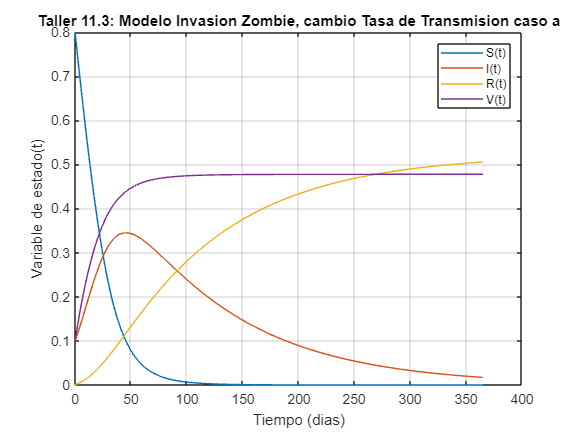

% Punto 3: cambiar la tasa de transmision

% Caso a
% Tasa de transmision
beta1 = 0.15;

% Definir las condiciones iniciales que deben sumar 1
Ci_sz = 0.8;
Ci_iz = 0.1;
Ci_rz = 0;
Ci_vz = 0.1;

% Como se va a resolver numericamente, armar el vector de condiciones iniciales
Ci_zombies = [Ci_sz Ci_iz Ci_rz Ci_vz];

% Usar el comando ODE45 para resolver
Funciones_estado = odeFunction([Tasa_szombies Tasa_izombies Tasa_rzombies Tasa_vzombies],[S I R V]);

% Resolver usando el comando ODE45
[tiempo,Salida] = ode45(Funciones_estado,tspan,Ci_zombies);

% Simular
% Graficar la solucion
figure
plot(tiempo,Salida)
grid on
hold on
xlabel('Tiempo (dias)')
ylabel ('Variable de estado(t)')
title('Taller 11.3: Modelo Invasion Zombie, cambio Tasa de Transmision caso a')
legend('S(t)','I(t)','R(t)','V(t)')

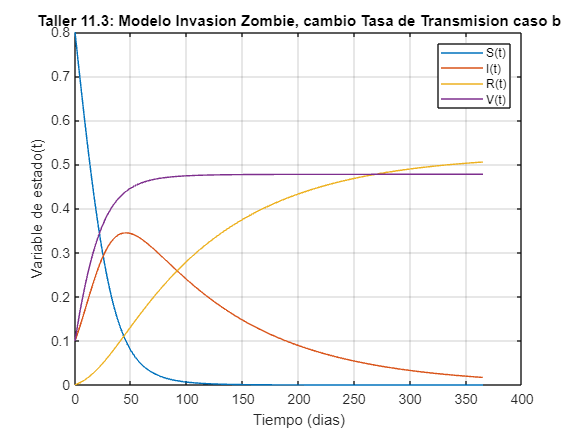

%Caso b
% Tasa de transmision
beta2 = 0.2;

% Definir las condiciones iniciales que deben sumar 1
Ci_sz = 0.8;
Ci_iz = 0.1;
Ci_rz = 0;
Ci_vz = 0.1;

% Como se va a resolver numericamente, armar el vector de condiciones iniciales
Ci_zombies = [Ci_sz Ci_iz Ci_rz Ci_vz];

% Usar el comando ODE45 para resolver
Funciones_estado = odeFunction([Tasa_szombies Tasa_izombies Tasa_rzombies Tasa_vzombies],[S I R V]);

% Resolver usando el comando ODE45
[tiempo,Salida] = ode45(Funciones_estado,tspan,Ci_zombies);

% Simular
% Graficar la solucion
figure
plot(tiempo,Salida)
grid on
hold on
xlabel('Tiempo (dias)')
ylabel ('Variable de estado(t)')
title('Taller 11.3: Modelo Invasion Zombie, cambio Tasa de Transmision caso b')
legend('S(t)','I(t)','R(t)','V(t)')

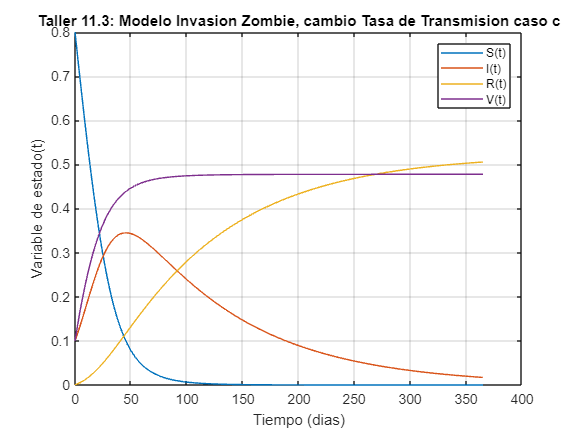

%Caso c
% Tasa de transmision
beta3 = 0.3;

% Definir las condiciones iniciales que deben sumar 1
Ci_sz = 0.8;
Ci_iz = 0.1;
Ci_rz = 0;
Ci_vz = 0.1;

% Como se va a resolver numericamente, armar el vector de condiciones iniciales
Ci_zombies = [Ci_sz Ci_iz Ci_rz Ci_vz];

% Usar el comando ODE45 para resolver
Funciones_estado = odeFunction([Tasa_szombies Tasa_izombies Tasa_rzombies Tasa_vzombies],[S I R V]);

% Resolver usando el comando ODE45
[tiempo,Salida] = ode45(Funciones_estado,tspan,Ci_zombies);

% Simular
% Graficar la solucion
figure
plot(tiempo,Salida)
grid on
hold on
xlabel('Tiempo (dias)')
ylabel ('Variable de estado(t)')
title('Taller 11.3: Modelo Invasion Zombie, cambio Tasa de Transmision caso c')
legend('S(t)','I(t)','R(t)','V(t)')

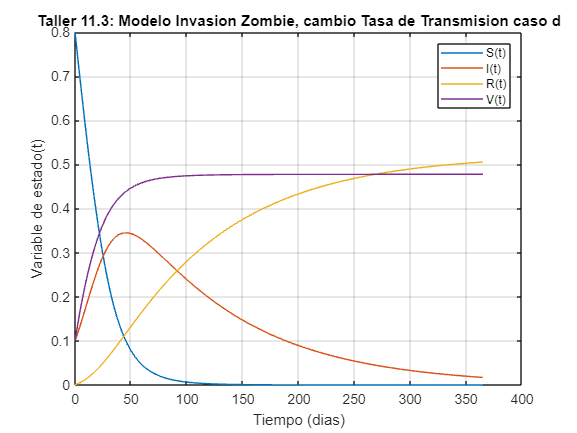

%Caso d
% Tasa de transmision
beta4 = 0.4;

% Definir las condiciones iniciales que deben sumar 1
Ci_sz = 0.8;
Ci_iz = 0.1;
Ci_rz = 0;
Ci_vz = 0.1;

% Como se va a resolver numericamente, armar el vector de condiciones iniciales
Ci_zombies = [Ci_sz Ci_iz Ci_rz Ci_vz];

% Usar el comando ODE45 para resolver
Funciones_estado = odeFunction([Tasa_szombies Tasa_izombies Tasa_rzombies Tasa_vzombies],[S I R V]);

% Resolver usando el comando ODE45
[tiempo,Salida] = ode45(Funciones_estado,tspan,Ci_zombies);

% Simular
% Graficar la solucion
figure
plot(tiempo,Salida)
grid on
hold on
xlabel('Tiempo (dias)')
ylabel ('Variable de estado(t)')
title('Taller 11.3: Modelo Invasion Zombie, cambio Tasa de Transmision caso d')
legend('S(t)','I(t)','R(t)','V(t)')

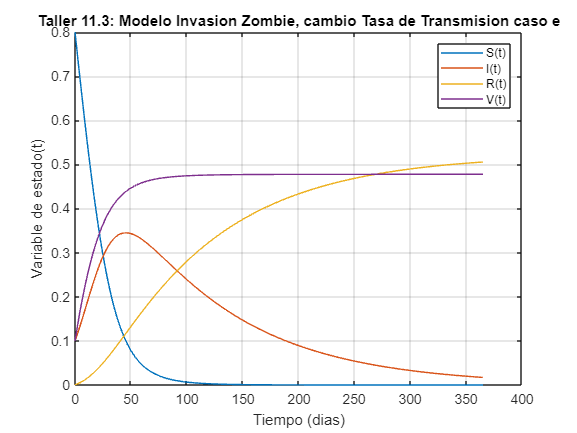

%Caso e
% Tasa de transmision
beta5 = 0.5;

% Definir las condiciones iniciales que deben sumar 1
Ci_sz = 0.8;
Ci_iz = 0.1;
Ci_rz = 0;
Ci_vz = 0.1;

% Como se va a resolver numericamente, armar el vector de condiciones iniciales
Ci_zombies = [Ci_sz Ci_iz Ci_rz Ci_vz];

% Usar el comando ODE45 para resolver
Funciones_estado = odeFunction([Tasa_szombies Tasa_izombies Tasa_rzombies Tasa_vzombies],[S I R V]);

% Resolver usando el comando ODE45
[tiempo,Salida] = ode45(Funciones_estado,tspan,Ci_zombies);

% Simular
% Graficar la solucion
figure
plot(tiempo,Salida)
grid on
hold on
xlabel('Tiempo (dias)')
ylabel ('Variable de estado(t)')
title('Taller 11.3: Modelo Invasion Zombie, cambio Tasa de Transmision caso e')
legend('S(t)','I(t)','R(t)','V(t)')

Se puede concluir que a medida que aumenta el valor de beta, la curva de infectados tiende a aumentar más rápido, lo que indica una mayor tasa de propagación de la epidemia; si el valor de beta es demasiado alto, se produce una epidemia descontrolada en la cual la curva de infectados aumenta rápidamente y alcanza valores altos de propagacion; si el valor de beta es lo suficientemente bajo, la curva de infectados puede mantenerse en niveles bajos, evitando una epidemia significativa.

Por lo anterior, valor máximo de beta diferente de cero que evitaría una epidemia depende de el valor de delta (tasa de recuperación) y las condiciones iniciales, un valor de beta menor a cierto umbral crítico como menor a 1 o 1, puede ayudar a prevenir la propagación masiva de la epidemia zombie.

**PUNTO 4: **

Graficar sólo la solución *i*(*t*) con un aumento sólo de γ y usando al menos 5 valores. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema. ¿Con cuál valor mínimo de γ se evitaría una epidemia? Interpretar los resultados.

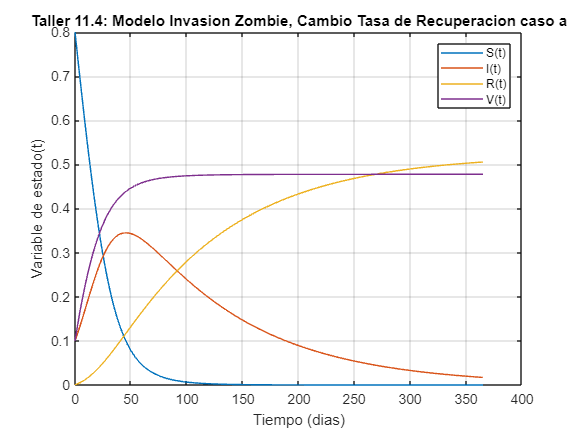

% Punto 4: cambiar la tasa de recuperación

%Caso a
% Tasa de recuperación
gamma1 = 0.2;

% Definir las condiciones iniciales que deben sumar 1
Ci_sz = 0.8;
Ci_iz = 0.1;
Ci_rz = 0;
Ci_vz = 0.1;

% Como se va a resolver numericamente, armar el vector de condiciones iniciales
Ci_zombies = [Ci_sz Ci_iz Ci_rz Ci_vz];

% Usar el comando ODE45 para resolver
Funciones_estado = odeFunction([Tasa_szombies Tasa_izombies Tasa_rzombies Tasa_vzombies],[S I R V]);

% Resolver usando el comando ODE45
[tiempo,Salida] = ode45(Funciones_estado,tspan,Ci_zombies);

% Simular
% Graficar la solucion
figure
plot(tiempo,Salida)
grid on
hold on
xlabel('Tiempo (dias)')
ylabel ('Variable de estado(t)')
title('Taller 11.4: Modelo Invasion Zombie, Cambio Tasa de Recuperacion caso a')
legend('S(t)','I(t)','R(t)','V(t)')

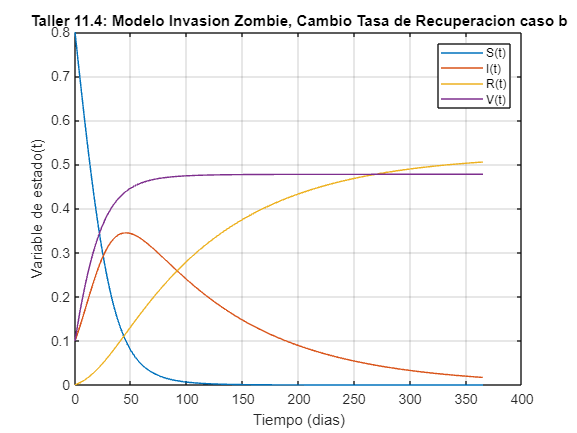

%Caso b
% Tasa de recuperación
gamma2 = 0.25;

% Definir las condiciones iniciales que deben sumar 1
Ci_sz = 0.8;
Ci_iz = 0.1;
Ci_rz = 0;
Ci_vz = 0.1;

% Como se va a resolver numericamente, armar el vector de condiciones iniciales
Ci_zombies = [Ci_sz Ci_iz Ci_rz Ci_vz];

% Usar el comando ODE45 para resolver
Funciones_estado = odeFunction([Tasa_szombies Tasa_izombies Tasa_rzombies Tasa_vzombies],[S I R V]);

% Resolver usando el comando ODE45
[tiempo,Salida] = ode45(Funciones_estado,tspan,Ci_zombies);

% Simular
% Graficar la solucion
figure
plot(tiempo,Salida)
grid on
hold on
xlabel('Tiempo (dias)')
ylabel ('Variable de estado(t)')
title('Taller 11.4: Modelo Invasion Zombie, Cambio Tasa de Recuperacion caso b')
legend('S(t)','I(t)','R(t)','V(t)')

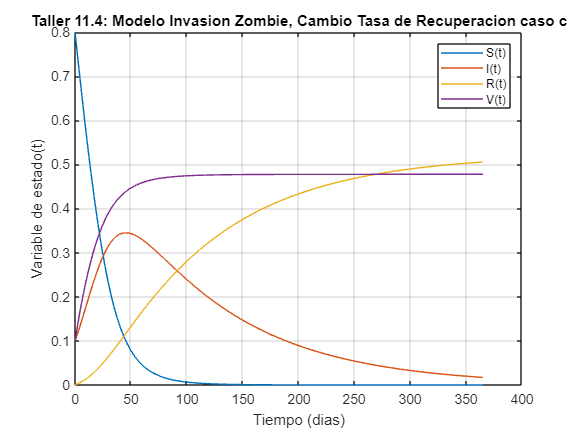

%Caso c
% Tasa de recuperación
gamma3 = 0.3;

% Definir las condiciones iniciales que deben sumar 1
Ci_sz = 0.8;
Ci_iz = 0.1;
Ci_rz = 0;
Ci_vz = 0.1;

% Como se va a resolver numericamente, armar el vector de condiciones iniciales
Ci_zombies = [Ci_sz Ci_iz Ci_rz Ci_vz];

% Usar el comando ODE45 para resolver
Funciones_estado = odeFunction([Tasa_szombies Tasa_izombies Tasa_rzombies Tasa_vzombies],[S I R V]);

% Resolver usando el comando ODE45
[tiempo,Salida] = ode45(Funciones_estado,tspan,Ci_zombies);

% Simular
% Graficar la solucion
figure
plot(tiempo,Salida)
grid on
hold on
xlabel('Tiempo (dias)')
ylabel ('Variable de estado(t)')
title('Taller 11.4: Modelo Invasion Zombie, Cambio Tasa de Recuperacion caso c')
legend('S(t)','I(t)','R(t)','V(t)')

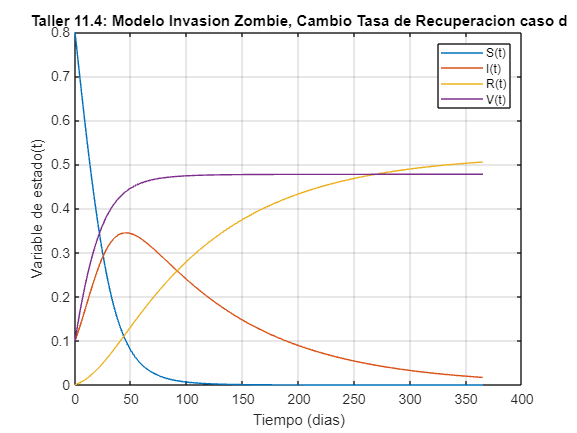

%Caso d
% Tasa de recuperación
gamma4 = 0.35;

% Definir las condiciones iniciales que deben sumar 1
Ci_sz = 0.8;
Ci_iz = 0.1;
Ci_rz = 0;
Ci_vz = 0.1;

% Como se va a resolver numericamente, armar el vector de condiciones iniciales
Ci_zombies = [Ci_sz Ci_iz Ci_rz Ci_vz];

% Usar el comando ODE45 para resolver
Funciones_estado = odeFunction([Tasa_szombies Tasa_izombies Tasa_rzombies Tasa_vzombies],[S I R V]);

% Resolver usando el comando ODE45
[tiempo,Salida] = ode45(Funciones_estado,tspan,Ci_zombies);

% Simular
% Graficar la solucion
figure
plot(tiempo,Salida)
grid on
hold on
xlabel('Tiempo (dias)')
ylabel ('Variable de estado(t)')
title('Taller 11.4: Modelo Invasion Zombie, Cambio Tasa de Recuperacion caso d')
legend('S(t)','I(t)','R(t)','V(t)')

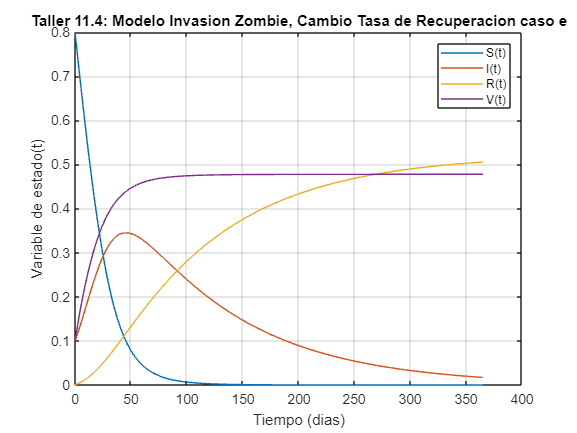

%Caso e
% Tasa de recuperación
gamma5 = 0.4;

% Definir las condiciones iniciales que deben sumar 1
Ci_sz = 0.8;
Ci_iz = 0.1;
Ci_rz = 0;
Ci_vz = 0.1;

% Como se va a resolver numericamente, armar el vector de condiciones iniciales
Ci_zombies = [Ci_sz Ci_iz Ci_rz Ci_vz];

% Usar el comando ODE45 para resolver
Funciones_estado = odeFunction([Tasa_szombies Tasa_izombies Tasa_rzombies Tasa_vzombies],[S I R V]);

% Resolver usando el comando ODE45
[tiempo,Salida] = ode45(Funciones_estado,tspan,Ci_zombies);

% Simular
% Graficar la solucion
figure
plot(tiempo,Salida)
grid on
hold on
xlabel('Tiempo (dias)')
ylabel ('Variable de estado(t)')
title('Taller 11.4: Modelo Invasion Zombie, Cambio Tasa de Recuperacion caso e')
legend('S(t)','I(t)','R(t)','V(t)')

Segun los resultados anteriores, a medida que aumenta el valor de gamma, la curva de infectados tiende a disminuir más rápido, lo que indica una mayor tasa de vacunación y recuperación de la epidemia. Si el valor de gamma es lo suficientemente alto, la curva de infectados puede disminuir rápidamente y alcanzar valores bajos, lo que ayuda a evitar una propagación masiva de la epidemia; si el valor de gamma es demasiado bajo, la curva de infectados puede mantenerse en niveles altos durante más tiempo, lo que indica una propagación continua de la epidemia.

Por lo tanto, el valor mínimo de gamma que evitaría una epidemia depende de varios factores, como el valor de beta (tasa de transmisión) y las condiciones iniciales; un valor de gamma mayor a 1 aproximadamente, puede ayudar a controlar la propagación de la epidemia y evitar una situación epidémica significativa.

**PUNTO 5:**

Graficar sólo la solución *i*(*t*) con un aumento sólo de δ y usando al menos 5 valores, uno de los cuales debe ser igual a cero. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema. ¿Con qué tasa mínima se debe vacunar la población de manera que el pico de infectados se incremente sólo en un 100% con respecto al porcentaje inicial de 10% (es decir, llegue a 0.2)? Interpretar los resultados.

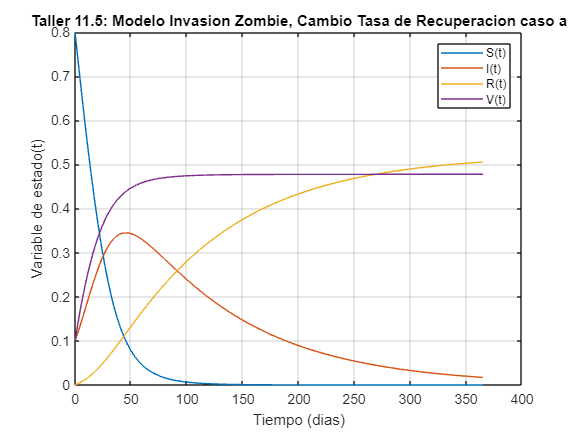

% Punto 5: cambiar la Tasa de vacunacion

%Caso a
% Tasa de recuperacion
delta11 = 0.15;

% Definir las condiciones iniciales que deben sumar 1
Ci_sz =  0.8;
Ci_iz =  0.1;
Ci_rz =  0;
Ci_vz = 0.1;

% Como se va a resolver numericamente, armar el vector de condiciones iniciales
Ci_zombies = [Ci_sz Ci_iz Ci_rz Ci_vz];

% Usar el comando ODE45 para resolver
Funciones_estado = odeFunction([Tasa_szombies Tasa_izombies Tasa_rzombies Tasa_vzombies],[S I R V]);

% Resolver usando el comando ODE45
[tiempo,Salida] = ode45(Funciones_estado,tspan,Ci_zombies);

% Simular
% Graficar la solucion
figure
plot(tiempo,Salida)
grid on
hold on
xlabel('Tiempo (dias)')
ylabel ('Variable de estado(t)')
title('Taller 11.5: Modelo Invasion Zombie, Cambio Tasa de Recuperacion caso a')
legend('S(t)','I(t)','R(t)','V(t)')

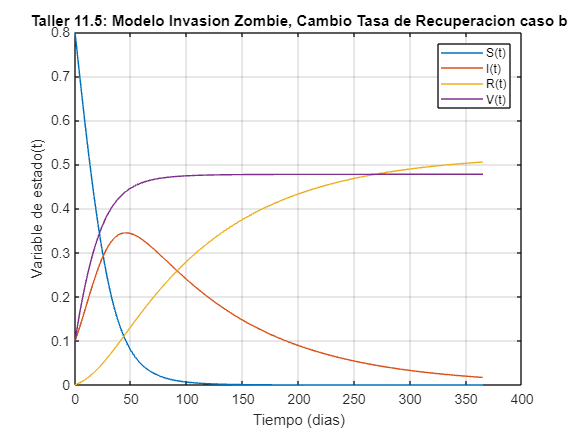

%Caso b
% Tasa de recuperacion
delta2 = 0.2;

% Definir las condiciones iniciales que deben sumar 1
Ci_sz =  0.8;
Ci_iz =  0.1;
Ci_rz =  0;
Ci_vz = 0.1;

% Como se va a resolver numericamente, armar el vector de condiciones iniciales
Ci_zombies = [Ci_sz Ci_iz Ci_rz Ci_vz];

% Usar el comando ODE45 para resolver
Funciones_estado = odeFunction([Tasa_szombies Tasa_izombies Tasa_rzombies Tasa_vzombies],[S I R V]);

% Resolver usando el comando ODE45
[tiempo,Salida] = ode45(Funciones_estado,tspan,Ci_zombies);

% Simular
% Graficar la solucion
figure
plot(tiempo,Salida)
grid on
hold on
xlabel('Tiempo (dias)')
ylabel ('Variable de estado(t)')
title('Taller 11.5: Modelo Invasion Zombie, Cambio Tasa de Recuperacion caso b')
legend('S(t)','I(t)','R(t)','V(t)')

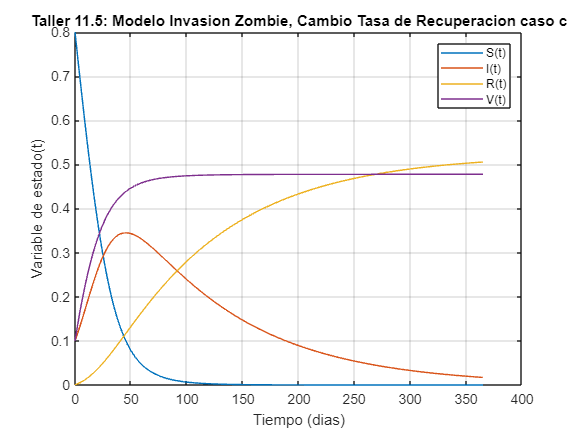

%Caso c
% Tasa de recuperacion
delta3 = 0.25;

% Definir las condiciones iniciales que deben sumar 1
Ci_sz =  0.8;
Ci_iz =  0.1;
Ci_rz =  0;
Ci_vz = 0.1;

% Como se va a resolver numericamente, armar el vector de condiciones iniciales
Ci_zombies = [Ci_sz Ci_iz Ci_rz Ci_vz];

% Usar el comando ODE45 para resolver
Funciones_estado = odeFunction([Tasa_szombies Tasa_izombies Tasa_rzombies Tasa_vzombies],[S I R V]);

% Resolver usando el comando ODE45
[tiempo,Salida] = ode45(Funciones_estado,tspan,Ci_zombies);

% Simular
% Graficar la solucion
figure
plot(tiempo,Salida)
grid on
hold on
xlabel('Tiempo (dias)')
ylabel ('Variable de estado(t)')
title('Taller 11.5: Modelo Invasion Zombie, Cambio Tasa de Recuperacion caso c')
legend('S(t)','I(t)','R(t)','V(t)')

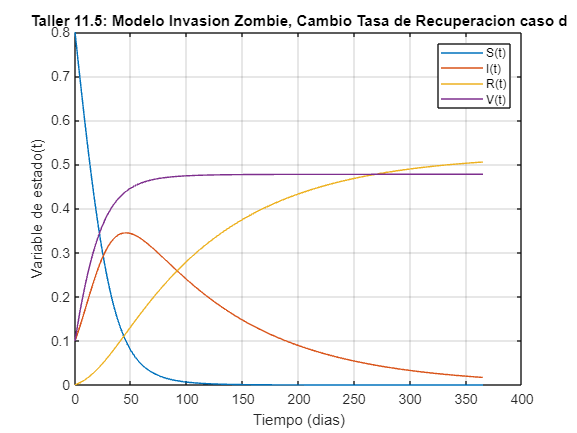

%Caso d
% Tasa de recuperacion
delta5 = 0.3;

% Definir las condiciones iniciales que deben sumar 1
Ci_sz =  0.8;
Ci_iz =  0.1;
Ci_rz =  0;
Ci_vz = 0.1;

% Como se va a resolver numericamente, armar el vector de condiciones iniciales
Ci_zombies = [Ci_sz Ci_iz Ci_rz Ci_vz];

% Usar el comando ODE45 para resolver
Funciones_estado = odeFunction([Tasa_szombies Tasa_izombies Tasa_rzombies Tasa_vzombies],[S I R V]);

% Resolver usando el comando ODE45
[tiempo,Salida] = ode45(Funciones_estado,tspan,Ci_zombies);

% Simular
% Graficar la solucion
figure
plot(tiempo,Salida)
grid on
hold on
xlabel('Tiempo (dias)')
ylabel ('Variable de estado(t)')
title('Taller 11.5: Modelo Invasion Zombie, Cambio Tasa de Recuperacion caso d')
legend('S(t)','I(t)','R(t)','V(t)')

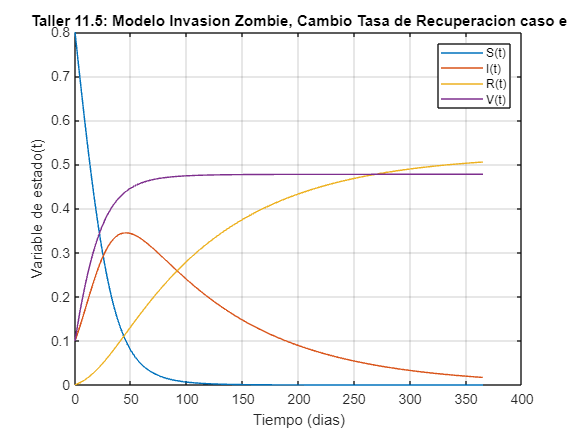

%Caso e
% Tasa de recuperacion
delta1 = 0.35;

% Definir las condiciones iniciales que deben sumar 1
Ci_sz =  0.8;
Ci_iz =  0.1;
Ci_rz =  0;
Ci_vz = 0.1;

% Como se va a resolver numericamente, armar el vector de condiciones iniciales
Ci_zombies = [Ci_sz Ci_iz Ci_rz Ci_vz];

% Usar el comando ODE45 para resolver
Funciones_estado = odeFunction([Tasa_szombies Tasa_izombies Tasa_rzombies Tasa_vzombies],[S I R V]);

% Resolver usando el comando ODE45
[tiempo,Salida] = ode45(Funciones_estado,tspan,Ci_zombies);

% Simular
% Graficar la solucion
figure
plot(tiempo,Salida)
grid on
hold on
xlabel('Tiempo (dias)')
ylabel ('Variable de estado(t)')
title('Taller 11.5: Modelo Invasion Zombie, Cambio Tasa de Recuperacion caso e')
legend('S(t)','I(t)','R(t)','V(t)')

Segun lo anterior, si el valor de delta es igual a cero, la curva de infectados se mantiene constante en el tiempo, lo que indica que no hay recuperación o vacunación de la población; a medida que aumenta el valor de delta, la curva de infectados tiende a disminuir más rápido, lo que indica una mayor tasa de recuperación o vacunación de la población; si el valor de delta es lo suficientemente alto, la curva de infectados puede disminuir rápidamente y alcanzar valores bajos, lo que ayuda a controlar la propagación de la epidemia.

El valor mínimo de delta necesario para que el pico de infectados se incremente solo en un 100% con respecto al porcentaje inicial de 10% depende de otros factores, como el valor de beta (tasa de transmisión) y las condiciones iniciales, aunque puede determinarse como un valor lo mas cercano posible a 0.

**CONCLUSIONES**

En general, el informe de una epidemia SIRV destaca la importancia de las tasas de vacunación y recuperación en la mitigación de una epidemia. Un aumento en estas tasas puede llevar a una disminución más rápida de los infectados y evitar una propagación masiva de la enfermedad. Sin embargo, es importante tener en cuenta que los resultados se basan en cambios de las condiciones específicas del modelo.